# Import AUTOSAR Composition to Simulink

Create Simulink® model from XML description of AUTOSAR software composition.

## Import AUTOSAR Composition from ARXML File to Simulink

Here is an AUTOSAR software composition that implements a throttle position control system. The composition contains six interconnected AUTOSAR software component prototypes -- four sensor/actuator components and two application components.

The composition was created in an AUTOSAR authoring tool and exported to the file `ThrottlePositionControlComposition.arxml`.

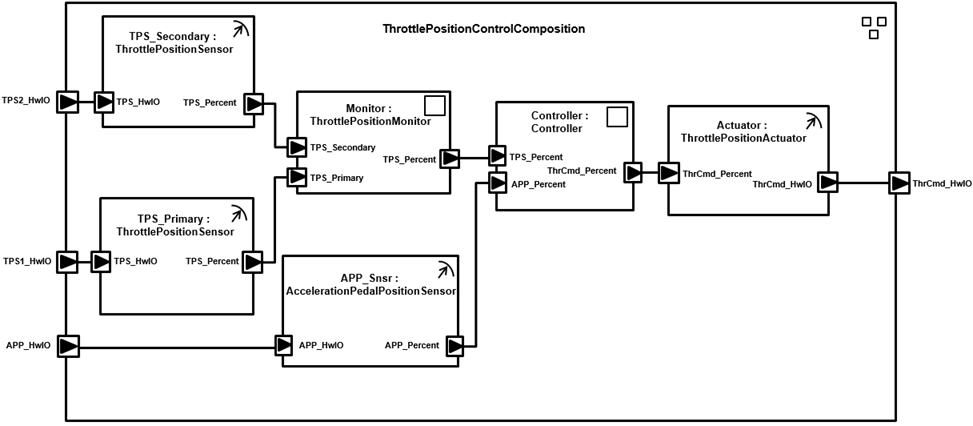

Use the MATLAB function [`createCompositionAsModel`](docid:autosar_ref.mw_dc934321-0764-484c-bfc8-d64ad5d6bb2c) to import the AUTOSAR XML (ARXML) description and create an initial Simulink representation of the AUTOSAR composition. First, parse the ARXML description file and list the compositions it contains.

ar = arxml.importer('ThrottlePositionControlComposition.arxml');
names = getComponentNames(ar,'Composition')

For the listed software composition, use `createCompositionAsModel` to create a Simulink representation. 

createCompositionAsModel(ar,'/Company/Components/ThrottlePositionControlComposition');

The function call creates a composition model that contains six component models, one for each atomic software component in the composition. Simulink inports and outports represent AUTOSAR ports and signal lines represent AUTOSAR component connectors.

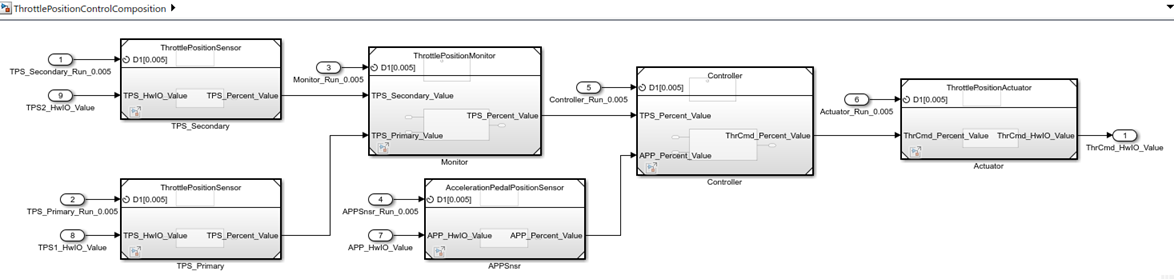

## Develop AUTOSAR Component Algorithms, Simulate, and Generate Code

After creating an initial Simulink representation of the AUTOSAR composition, you develop each component in the composition. For each component, you refine the AUTOSAR configuration and create algorithmic model content.

For example, the `Controller` component model in the `ThrottlePositionControlComposition` composition model contains an atomic subsystem `Runnable_Step_sys`, which represents an AUTOSAR periodic runnable. The `Runnable_Step_sys` subsystem contains the initial stub implementation of the controller behavior.

Here is a possible implementation of the throttle position controller behavior. (To explore this implementation, see the model `autosar_swc_controller`, which is provided with the example [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51).) The component takes as inputs an APP sensor percent value from a pedal position sensor and a TPS percent value from a throttle position sensor. Based on these values, the controller calculates the *error*. The error is the difference between where the operator wants the throttle, based on the pedal sensor, and the current throttle position. In this implementation, a Discrete PID Controller block uses the error value to calculate a throttle command percent value to provide to a throttle actuator. A scope displays the error value and the Discrete PID Controller block output value over time.

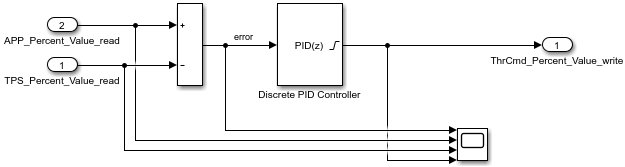

As you develop AUTOSAR components, you can:

- Simulate component models individually or together in a containing composition.

- Generate ARXML component description files and algorithmic C code for testing in Simulink or integration into an AUTOSAR run-time environment. (AUTOSAR code generation requires Simulink Coder and Embedded Coder.)

For more information on developing, simulating, and building AUTOSAR components, see example [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51).

## Update AUTOSAR Composition Model with Architectural Changes from Authoring Tool

Suppose that, after you imported the AUTOSAR software composition into Simulink and began developing algorithms, architectural changes were made to the composition in the AUTOSAR authoring tool.

Here is the revised composition. The changes delete a sensor component, add a logger component, and add ports and connections at the composition and component levels. In the AUTOSAR authoring tool, the revised composition is exported to the file `ThrottlePositionControlComposition_updated.arxml`.

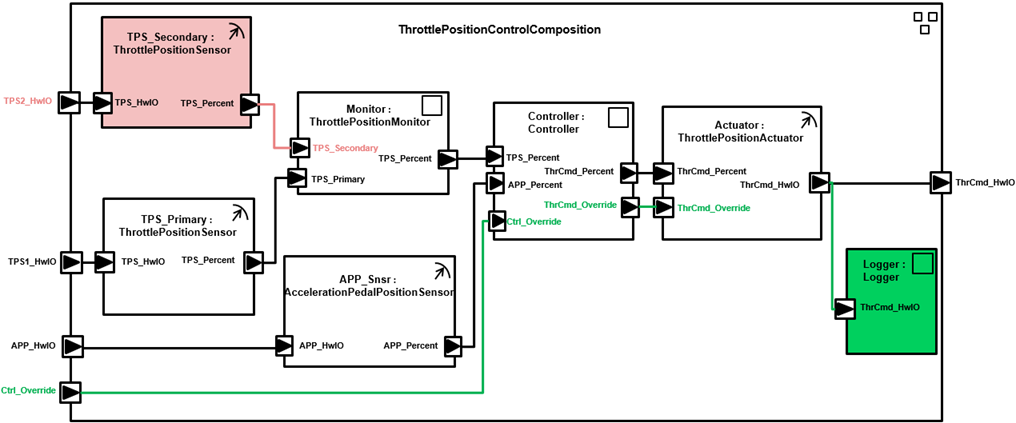

Use the MATLAB function [`updateModel`](docid:autosar_ref.mw_f3712731-00d9-4afa-91d6-6d42686c1505) to import the architectural revisions from the ARXML file. The function updates the AUTOSAR composition model with the changes and reports the results.

ar2 = arxml.importer('ThrottlePositionControlComposition_updated.arxml');
updateModel(ar2,'ThrottlePositionControlComposition');

After the update, in the composition model, highlighting indicates where changes occurred.

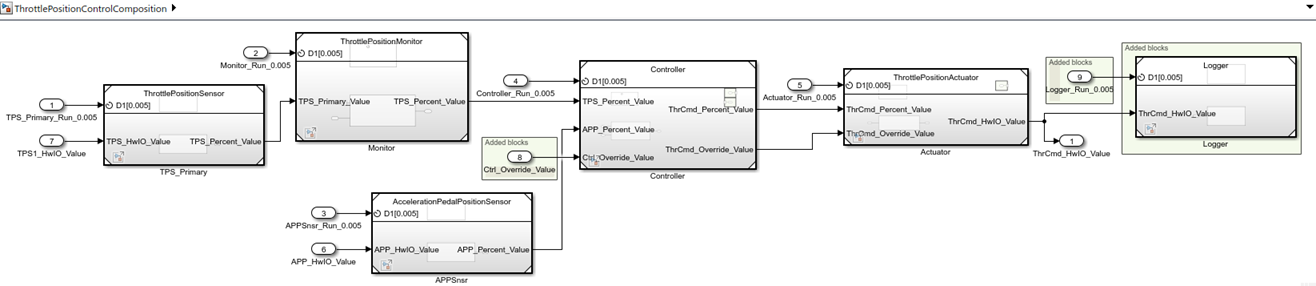

The function also generates and displays an HTML AUTOSAR update report. The report lists changes that the update made to Simulink and AUTOSAR elements in the composition model. In the report, you can click hyperlinks to navigate from change descriptions to model changes, and to navigate from the main report to individual component reports.

## Related Links

- [`createCompositionAsModel`](docid:autosar_ref.mw_dc934321-0764-484c-bfc8-d64ad5d6bb2c)

- [`updateModel`](docid:autosar_ref.mw_f3712731-00d9-4afa-91d6-6d42686c1505)

- [AUTOSAR Component Creation](docid:autosar_doccenter.mw_04becf9f-83c3-4914-924b-0816a0405b0c)

- [Import AUTOSAR Software Component Updates](docid:autosar_ug.buax917-1)

- [Design AUTOSAR Components, Simulate, and Generate Code](docid:autosar_ug.mw_2cca1e20-3bca-4a1a-b954-8021e1cc3c51)

*Copyright 2018-2020 The MathWorks, Inc.*